# Sensor Calibration

1--Prompt the user to position the ball. Use the command pause and then press the space bar to

continue when ready.

2--Collect N = 3 measurements at each position of ball. There are M = 15 positions.

3--Store the data to an array.

Open port to Pico

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


sensor = zeros(14,3); % initialize empy array for sensor values

% loop through rows in sensor array
for m = 1:size(sensor,1)
    fprintf("Please position the ball to hole: #" + m + "\n") % prompt user to position ball
    pause % wait until user keyboard input
    % loop through columns in sensor array
    for n = 1:size(sensor,2)
        s.writeline("read") % write "read" to Pico
        sensor(m,n) = s.readline(); % read ADC value from Pico
        pause(0.5) % wait 0.5 second
    end
end

Please position the ball to hole: #1
Please position the ball to hole: #2
Please position the ball to hole: #3
Please position the ball to hole: #4
Please position the ball to hole: #5
Please position the ball to hole: #6
Please position the ball to hole: #7
Please position the ball to hole: #8
Please position the ball to hole: #9
Please position the ball to hole: #10
Please position the ball to hole: #11
Please position the ball to hole: #12
Please position the ball to hole: #13
Please position the ball to hole: #14


4--Save the collected data in a file called sensor_calibration_DATE.mat

save sensor_calibration_04_16_2024.mat sensor

Load the file `sensor_calibration_DATE.mat` from EXP.6 onto MATLAB.

load sensor_calibration_03_19_2024.mat
sensor

sensor =        20613       20292       20228
       32039       31799       49420
       64255       46011       45931
       41178       41354       41242
       33384       34600       33992
       28598       28582       29159
       25398       24774       24758
       22869       22741       22949
       20949       23093       21557
       19172       19284       18964


A more accurate relationship between ADC output voltage, *V*, and ball position, *D*, is

the following second-order polynomial:

*V *= *a ∙ D*^2 + *b ∙ D* + *c*

From the plot of voltage vs. position data, identify a range on the horizontal axis where the

markers seem to follow a parabola (e.g., form holes #4 to #15). In MATLAB, do the following:

1--For each position in the selected range find the mean value of the *N* = 3 measurements taken.

average = trimmean(sensor,50,2); % take a 50% trimmed mean to remove bias from outliers
position = (3:14); % index for range of holes to find polynomial trend
voltage = average(position) % index average array using range of holes

voltage =        39097
       33256
       29367
       24197
       21813
       20372
       18228
       16884
       16820
       14915


2--`Use polyfit(position,voltage,2)` to solve for the parameters *a, b*, and *c* of the

best second-degree polynomial fit to all points in the selected interval.

parameters = polyfit(position,voltage,2); % calculate parameters for 2nd polynomial
% assign the parameters for the data
a = parameters(1)

a =      2.287500000000004e+02


b = parameters(2)

b =     -6.050886363636371e+03


c = parameters(3)

c =      5.397765909090912e+04


3--Using the calculated values for parameters *a, b*, and *c* plot the best curve fit inside the

selected range and overlay the markers of the experimental measurements.

Discuss whether the curve passes closely from the markers inside the selected interval.

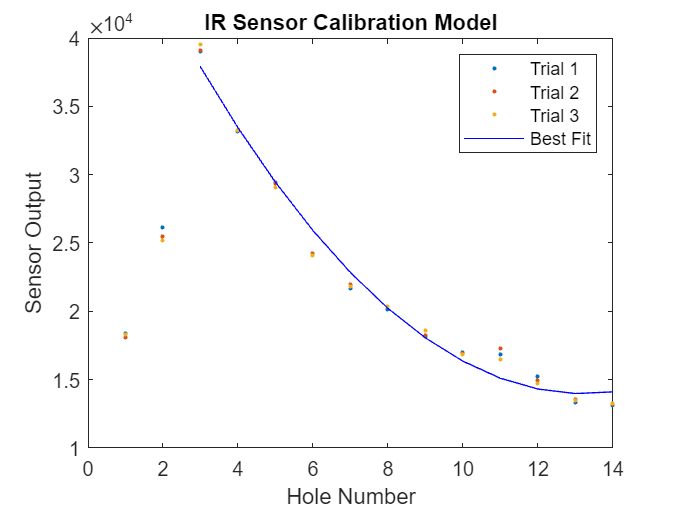

V = a * position.^2 + b * position + c; % calculate curve using calculated parameters

plot(sensor, '.') % overlay experimental measurments
hold on
plot(position, V, 'b') % plot curve
title("IR Sensor Calibration Model")
xlabel("Hole Number")
ylabel("Sensor Output")
legend("Trial 1", "Trial 2", "Trial 3", "Best Fit")
hold off

For the purpose of closed-loop ball levitation, the position of the ball corresponding to

the sensor output is needed. To find the parameters *c*, *e*, and* f *of the inverse relationship

*D = c ∙ V*^2 +* e ∙ V + f*

repeat Step 2 with `polyfit(voltage,position,2)`.

parameters = polyfit(voltage,position,2); % calculate parameters for 2nd polynomial
% assign the parameters for the data
format long
c = parameters(1)

c =      1.811770357821075e-08


e = parameters(2)

e =   -0.001330867669621


f = parameters(3)

f =   27.771404790485644
